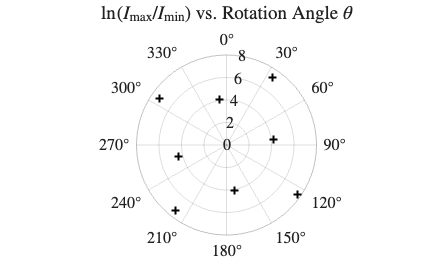

% Data
angles_deg = [34, 83, 125, 170, 218, 257, 305, 351];
I_max = [858, 841, 869, 815, 844, 859, 851, 806];
I_min = [0.6, 12.8, 0.4, 13.4, 0.5, 10.5, 0.6, 13.8];

% Calculate natural log ratio
ln_ratios = log(I_max ./ I_min);

% Prepare data for a closed-loop polar plot
theta = deg2rad([angles_deg, angles_deg(1)]);
r_plot = [ln_ratios, ln_ratios(1)];

% Create Figure
figure('Color', 'w');
p = polarplot(theta, r_plot, '+k', 'LineWidth', 1.5, 'MarkerFaceColor', 'k');

% Set Font to Times New Roman and use LaTeX for Title/Labels
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
title('$\ln(I_{\max}/I_{\min})$ vs. Rotation Angle $\theta$', ...
      'Interpreter', 'latex', 'FontSize', 14);

% Adjust Polar Axes to Lab Standards
grid off;
ax = gca;
ax.ThetaZeroLocation = 'top'; 
ax.ThetaDir = 'clockwise';
ax.TickLabelInterpreter = 'latex';

grid on;

% 1. Data Input
angles_deg = [34, 83, 125, 170, 218, 257, 305, 351]';
I_max = [858, 841, 869, 815, 844, 859, 851, 806]';
I_min = [0.6, 12.8, 0.4, 13.4, 0.5, 10.5, 0.6, 13.8]';
y = log(I_max ./ I_min);
x = deg2rad(angles_deg); % Convert to radians for fitting

% 2. Define the Cosine Model: a*cos(4*x + c) + d
ft = fittype('a*cos(4*x + c) + d', 'independent', 'x');
opts = fitoptions(ft);
opts.StartPoint = [1.7, -2.3, 5.8]; % Initial guesses for [a, c, d]

% Perform Fit
[fitresult, gof] = fit(x, y, ft, opts);

% 3. Visualization in Cartesian Coordinates
figure('Color', 'w');
plot(angles_deg, y, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Experimental Data'); 
hold on;

theta_fine_deg = linspace(0, 360, 500);
theta_fine_rad = deg2rad(theta_fine_deg);
y_fit = fitresult.a * cos(4*theta_fine_rad + fitresult.c) + fitresult.d;

plot(theta_fine_deg, y_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Cosine Fit');

% 4. Professional Formatting (Times New Roman & LaTeX)
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
xlabel('Rotation Angle $\theta$ ($^\circ$)', 'Interpreter', 'latex');
ylabel('$\ln(I_{\max}/I_{\min})$', 'Interpreter', 'latex');
%title('$\ln(I_{\max}/I_{\min})$ vs. Rotation Angle $\theta$', ...
%      'Interpreter', 'latex', 'FontSize', 14);

xlim([0 360]);
xticks(0:45:360);
grid on;
legend('Location', 'best', 'Interpreter', 'latex');

% Output Fit Parameters to Command Window
fprintf('Fit equation: %.2f * cos(4*theta + %.2f) + %.2f\n', fitresult.a, fitresult.c, fitresult.d);

Fit equation: 1.70 * cos(4*theta + -2.77) + 5.79


fprintf('R-square: %.4f\n', gof.rsquare);

R-square: 0.9935


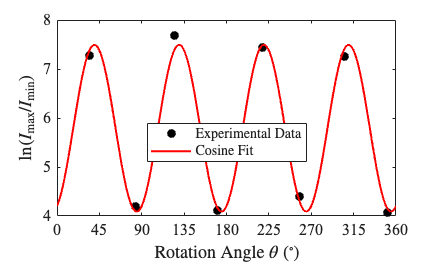


grid off;

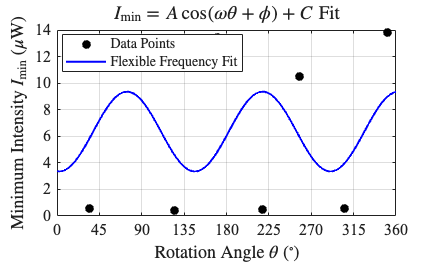

% 1. Experimental Data
theta_deg = [34, 83, 125, 170, 218, 257, 305, 351]';
I_min = [0.6, 12.8, 0.4, 13.4, 0.5, 10.5, 0.6, 13.8]';
t_rad = deg2rad(theta_deg); 

% 2. Define the Model: A*cos(w*t + phi) + C
% 'w' is now a free parameter to be determined by the data
ft = fittype('A*cos(w*t + phi) + C', 'independent', 't', 'coefficients', {'A', 'w', 'phi', 'C'});
opts = fitoptions(ft);

% Initial guesses: A=6, w=2 (expected), phi=-2.8, C=7
opts.StartPoint = [6, 2, -2.8, 7]; 
opts.Lower = [0, 1.5, -pi*2, 0];   % Constraints to keep w near expected value
opts.Upper = [15, 2.5, pi*2, 15];

% Execute Fit
[fitresult, gof] = fit(t_rad, I_min, ft, opts);

% 3. Generate Curve for Plotting
theta_fine_deg = linspace(0, 360, 1000);
t_fine_rad = deg2rad(theta_fine_deg);
y_fit = fitresult.A * cos(fitresult.w * t_fine_rad + fitresult.phi) + fitresult.C;

% 4. Cartesian Plotting
figure('Color', 'w');
plot(theta_deg, I_min, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Data Points');
hold on;
plot(theta_fine_deg, y_fit, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Flexible Frequency Fit');

% 5. Professional Formatting
set(gca, 'FontName', 'Times New Roman', 'FontSize', 12);
xlabel('Rotation Angle $\theta$ ($^\circ$)', 'Interpreter', 'latex');
ylabel('Minimum Intensity $I_{\min}$ ($\mu$W)', 'Interpreter', 'latex');
title('$I_{\min} = A\cos(\omega\theta + \phi) + C$ Fit', 'Interpreter', 'latex', 'FontSize', 14);

xlim([0 360]);
xticks(0:45:360);
grid on;
legend('Location', 'best', 'Interpreter', 'latex');


% Output results to Command Window
disp('--- Fit Parameters ---');

--- Fit Parameters ---


fprintf('Amplitude (A): %.4f\n', fitresult.A);

Amplitude (A): 2.9992


fprintf('Frequency (w): %.4f\n', fitresult.w);

Frequency (w): 2.5000


fprintf('Phase (phi):   %.4f\n', fitresult.phi);

Phase (phi):   -3.2475


fprintf('Offset (C):    %.4f\n', fitresult.C);

Offset (C):    6.3537


fprintf('R-square:      %.4f\n', gof.rsquare);

R-square:      0.1175
